# **PCE tunnel  --  Multiple point-Bayesian inference**

## **1 - INITIALIZE UQLAB**

clc;clear all;close all;
clearvars
rng(100,'twister')
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\NY2023\D_document\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## 2 - ICFEP FE realization ${\mathcal{M}}(r)$

Four FE realization of ICFEP on tunnel 

including G01:G02:101 output settlement point

FE_realization = [323.6844995	153.8135462	0.00015318	0.00012089	8.14E-05	3.47E-05	-1.92E-05	-8.02E-05	-0.00014851	-0.00022398	-0.00030664	-0.00039649	-0.00049354	-0.00059778	-0.00070922	-0.00081815	-0.0009041	-0.00099679	-0.0010962	-0.0012024	-0.0013153	-0.0014349	-0.0015613	-0.0016945	-0.0018503	-0.0020576	-0.0023168	-0.0026279	-0.0029908	-0.0034056	-0.0038722	-0.0043907	-0.0049691	-0.0056375	-0.0063775	-0.0071891	-0.0080722	-0.0090182	-0.0099932	-0.010997	-0.012029	-0.013055	-0.014043	-0.014988	-0.015844	-0.016601	-0.017224	-0.017687	-0.017966	-0.018045	-0.01792	-0.017605	-0.017119	-0.016473	-0.015695	-0.014807	-0.013842	-0.012826	-0.011791	-0.010759	-0.0097543	-0.0087947	-0.0078858	-0.0070401	-0.006262	-0.0055628	-0.0049306	-0.0043653	-0.003867	-0.0034281	-0.0030408	-0.0027049	-0.0024205	-0.0021863	-0.0019782	-0.0017933	-0.0016314	-0.0014927	-0.0013771	-0.0012846	-0.0012152	-0.0011633	-0.0011045	-0.0010468	-0.00099031	-0.00093497	-0.0008808	-0.00082778	-0.00077593	-0.00072523	-0.00064984	-0.00057064	-0.00049649	-0.00042741	-0.00036339	-0.00030443	-0.00025053	-0.00020169	-0.00015791	-0.00011919	-8.55E-05	-5.69E-05	-3.34E-05
430.608477	324.5138651	0.00022496	0.00020074	0.00017052	0.00013431	9.21E-05	4.39E-05	-1.03E-05	-7.04E-05	-0.00013658	-0.00020873	-0.00028687	-0.000371	-0.00046112	-0.00054895	-0.00061656	-0.00068907	-0.00076647	-0.00084876	-0.00093595	-0.001028	-0.001125	-0.0012269	-0.0013345	-0.0014911	-0.0017029	-0.00197	-0.0022924	-0.00267	-0.0031029	-0.0035911	-0.0041432	-0.0047965	-0.0055338	-0.0063554	-0.0072611	-0.008255	-0.0092895	-0.010364	-0.01148	-0.012596	-0.013683	-0.014733	-0.015694	-0.016554	-0.017271	-0.017818	-0.018182	-0.018334	-0.018269	-0.017999	-0.017535	-0.016884	-0.016073	-0.01513	-0.014087	-0.012975	-0.011834	-0.010695	-0.0095809	-0.0085135	-0.0075017	-0.0065666	-0.0057217	-0.0049719	-0.0043023	-0.0037128	-0.0032035	-0.0027662	-0.0023863	-0.0020639	-0.0017988	-0.0015951	-0.0014185	-0.0012636	-0.0011305	-0.001019	-0.0009293	-0.0008613	-0.00081501	-0.00078475	-0.00074563	-0.00070557	-0.00066457	-0.00062264	-0.00057977	-0.00053597	-0.00049122	-0.00044555	-0.00038765	-0.00032916	-0.0002743	-0.00022307	-0.00017546	-0.00013147	-9.11E-05	-5.44E-05	-2.13E-05	8.22E-06	3.41E-05	5.63E-05	7.49E-05
599.0415205	399.4416458	0.00027796	0.00025525	0.00022726	0.00019397	0.00015538	0.0001115	6.23E-05	7.87E-06	-5.19E-05	-0.00011695	-0.0001873	-0.00026294	-0.00034388	-0.00042274	-0.00048349	-0.00054842	-0.00061754	-0.00069084	-0.00076833	-0.00085	-0.00093585	-0.0010259	-0.0011244	-0.0012745	-0.0014814	-0.0017452	-0.0020659	-0.0024434	-0.0028778	-0.0033691	-0.0039241	-0.0045756	-0.0053124	-0.0061345	-0.0070418	-0.0080291	-0.0090507	-0.010106	-0.011196	-0.012289	-0.013344	-0.014359	-0.015291	-0.016124	-0.016824	-0.017372	-0.017723	-0.017877	-0.017834	-0.017578	-0.017136	-0.0165	-0.015706	-0.014789	-0.013771	-0.012681	-0.011554	-0.010421	-0.00931	-0.0082443	-0.0072327	-0.0062946	-0.0054393	-0.0046814	-0.0040091	-0.0034224	-0.0029214	-0.0024943	-0.0021258	-0.0018159	-0.0015645	-0.0013752	-0.0012124	-0.0010707	-0.00095004	-0.00085036	-0.00077169	-0.00071404	-0.0006774	-0.00065334	-0.00061333	-0.00057404	-0.00053547	-0.00049762	-0.0004605	-0.0004241	-0.00038841	-0.00035345	-0.00030377	-0.00025215	-0.00020391	-0.00015906	-0.0001176	-7.95E-05	-4.48E-05	-1.35E-05	1.44E-05	3.89E-05	6.00E-05	7.78E-05	9.21E-05
708.0521538	240.1426234	0.00036608	0.00033469	0.00029803	0.00025609	0.00020888	0.0001564	9.87E-05	3.56E-05	-3.27E-05	-0.00010623	-0.00018507	-0.00026918	-0.00035856	-0.0004431	-0.0005027	-0.00056915	-0.00064245	-0.00072259	-0.00080958	-0.00090341	-0.0010041	-0.0011116	-0.0012371	-0.001414	-0.0016444	-0.0019283	-0.0022657	-0.0026567	-0.0031012	-0.0035991	-0.0041582	-0.0048067	-0.0055281	-0.0063222	-0.0071893	-0.0081225	-0.0090788	-0.010058	-0.01106	-0.012056	-0.013024	-0.013959	-0.014819	-0.015588	-0.016229	-0.016715	-0.017026	-0.01716	-0.017097	-0.016847	-0.016418	-0.01582	-0.015098	-0.01426	-0.013335	-0.012351	-0.011328	-0.010292	-0.0092685	-0.0082761	-0.0073237	-0.0064325	-0.0056091	-0.0048817	-0.0042315	-0.0036584	-0.003162	-0.0027123	-0.002325	-0.0019999	-0.0017372	-0.0015565	-0.0014048	-0.0012707	-0.0011542	-0.0010553	-0.00097402	-0.00091035	-0.00086427	-0.00082175	-0.00074958	-0.00068395	-0.00062487	-0.00057233	-0.00052634	-0.0004869	-0.00045401	-0.00042767	-0.00037921	-0.00032478	-0.00027322	-0.00022453	-0.00017871	-0.00013576	-9.57E-05	-5.85E-05	-2.41E-05	7.36E-06	3.60E-05	6.17E-05	8.46E-05
];
size(FE_realization)

ans =      4   103


Plot LHS sampling

LHS_G01 = FE_realization(:,1);
size(LHS_G01)

ans =      4     1


LHS_G02 = FE_realization(:,2);
size(LHS_G02)

ans =      4     1


scatter(LHS_G01,LHS_G02)
xlabel('G01');
ylabel('G02');
title('LHS sampling on G01 and G02')
box on;

plot the FE reliazation 

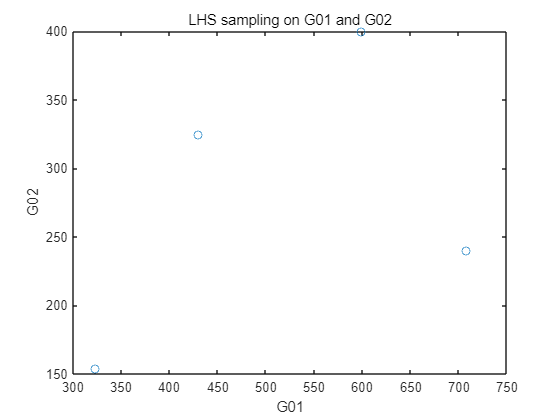

hold off;

X coordinates - FE settlement (4 realizations)

FE_Coordinate= [-110	-108	-105	-103	-101	-98.2	-95.9	-93.5	-91.2	-88.8	-86.5	-84.1	-81.8	-79.4	-77.1	-74.7	-72.4	-70	-67.7	-65.3	-63	-60.6	-58.3	-55.9	-53.6	-51.2	-48.8	-46.5	-44.1	-41.8	-39.4	-37.1	-34.7	-32.4	-30	-27.7	-25.3	-23	-20.6	-18.3	-15.9	-13.6	-11.2	-8.86	-6.51	-4.16	-1.81	0.544	2.9	5.25	7.6	9.95	12.3	14.7	17	19.4	21.7	24.1	26.4	28.8	31.1	33.5	35.8	38.2	40.5	42.9	45.2	47.6	49.9	52.3	54.6	57	59.3	61.7	64	66.4	68.8	71.1	73.5	75.8	78.2	80.5	82.9	85.2	87.6	89.9	92.3	94.6	97	99.3	102	104	106	109	111	113	116	118	121	123	125
]';
size(FE_Coordinate)

ans =    101     1


FE_Settlement = FE_realization(:,3:end)';
size(FE_Settlement)

ans =    101     4


FE_Coordinate_Settlement = [FE_Coordinate FE_Settlement];
size(FE_Coordinate_Settlement)

ans =    101     5


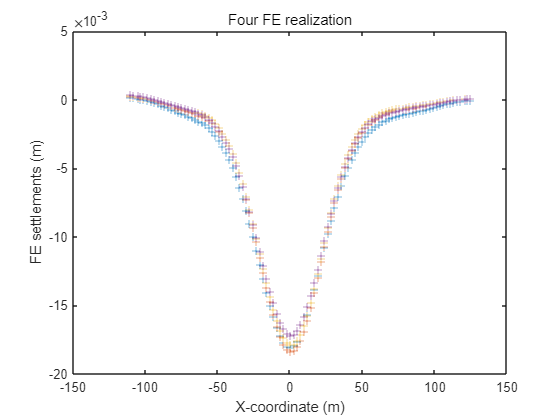


plot(FE_Coordinate_Settlement(:,1),FE_Coordinate_Settlement(:,2:5),'+');
xlabel('X-coordinate (m)');
ylabel("FE settlements (m)");
title('Four FE realization')

## 3 - PROBABILISTIC INPUT MODEL for PCE

Note: priors for PCE input, not for Bayesian inference prior input

G01 prior for PCE input

InputOpts.Marginals(1).Name = 'G01';
InputOpts.Marginals(1).Type = 'Uniform';
minG01 = min(FE_realization(:,1))

minG01 = 323.6845

maxG01 = max(FE_realization(:,1))

maxG01 = 708.0522

InputOpts.Marginals(1).Parameters  = [0.5*minG01 1.5*maxG01];

G02 prior for PCE input

InputOpts.Marginals(2).Name = 'G02';
InputOpts.Marginals(2).Type = 'Uniform';
minG02 = min(FE_realization(:,2))

minG02 = 153.8135


maxG02 = max(FE_realization(:,2))

maxG02 = 399.4416


InputOpts.Marginals(2).Parameters  = [0.2*minG02 3*maxG02];

myInput = uq_createInput(InputOpts);

## 4 - Change the Raw measurement  as equal length ---50 settlement points

**X Coordinate + y settlement**

Raw_Measurement = [-50.2	-0.000613181
-47.7	-0.000703181
-45.2	-0.001103181
-42.7	-0.000973181
-40.2	-0.001293181
-37.7	-0.001483181
-35.2	-0.001773181
-32.7	-0.002293181
-30.2	-0.002693181
-27.71	-0.003353181
-27.72	-0.003443181
-25.2	-0.004203181
-22.7	-0.005043181
-20.2	-0.006253181
-17.7	-0.007383181
-15.2	-0.008663181
-12.7	-0.010223181
-5	-0.013313181
-2.5	-0.013713181
0	-0.013773181
2.5	-0.013153181
5	-0.012233181
7.5	-0.010903181
10	-0.009483181
28.65	-0.002233181
31.15	-0.001663181
33.45	-0.001173181
35.95	-0.000933181
38.45	-0.000563181
40.95	-0.000423181

];
size(Raw_Measurement)

ans =     30     2


X_Raw_Measurement = Raw_Measurement(:,1);
size(X_Raw_Measurement)

ans =     30     1


Y_Raw_Measurement = Raw_Measurement(:,2);
size(Y_Raw_Measurement)

ans =     30     1


%fitting
%split the range into 50 points
Xmin = min(X_Raw_Measurement)

Xmin = -50.2000

Xmax = max(X_Raw_Measurement)

Xmax = 40.9500

X_Equal_length = linspace(Xmin,Xmax,50)';
size(X_Equal_length)

ans =     50     1


Y_Equal_length_Measurement = interp1(X_Raw_Measurement,Y_Raw_Measurement,X_Equal_length);
size(Y_Equal_length_Measurement)

ans =     50     1


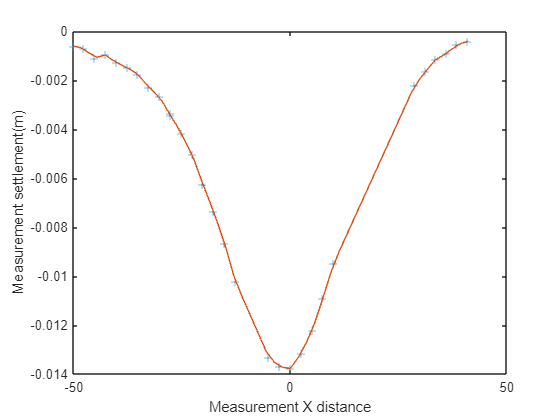

%plotting
plot(X_Raw_Measurement,Y_Raw_Measurement,'+');
hold on;
plot(X_Equal_length,Y_Equal_length_Measurement);
xlabel('Measurement X distance')
ylabel('Measurement settlement(m)')
hold off;

## 5 Change the FE outpout size equal length---50 settlement points

N_FE_realization = size(FE_realization,1)

N_FE_realization = 4

size(FE_Coordinate_Settlement)

ans =    101     5


FE_Equal_length = [];

Loop to get the new  equal length FE output 

for i = 1: N_FE_realization
    hold on;
    %fitting %interpolation
    X_FE = FE_Coordinate_Settlement(:,1);
    Y_FE = FE_Coordinate_Settlement(:,i+1);   


    Y_FE_Equal_length =  interp1(X_FE,Y_FE,X_Equal_length);

    FE_Equal_length = [FE_Equal_length Y_FE_Equal_length];

end
%plotting
close all;
plot(FE_Coordinate_Settlement(:,1),FE_Coordinate_Settlement(:,2:end),'+');
hold on;
plot(X_Equal_length,FE_Equal_length);
xlabel('FE X distance')
ylabel('FE settlement(m)')

Put the measurements into the figure and have a look

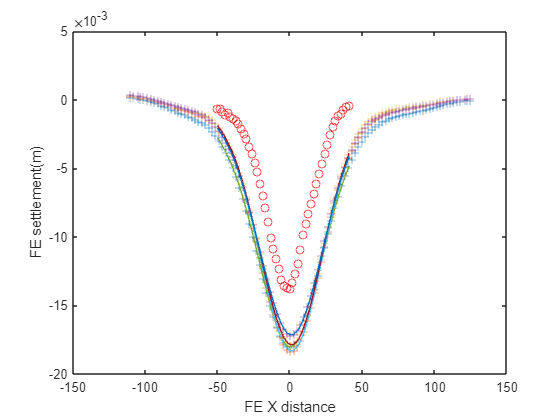

hold on;
plot(X_Equal_length,Y_Equal_length_Measurement,'o',Color='red');

## 6 - POLYNOMIAL CHAOS EXPANSION (PCE) METAMODELS $\tilde{\mathcal{M}}(r)$

Calculate the polynomial chaos expansion (PCE) coefficients.

Select PCE as the metamodeling tool in UQLab:

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';

Select the BCS for the PCE coefficients calculation strategy:

Specify the sparse truncation scheme (hyperbolic norm with ):

metaopts.Method = 'BCS';
%metaopts.TruncOptions.qNorm = 0.75;

Select the PCE options and create the PCE model:

metaopts.Degree = 2:15;

Experimental design

X = FE_realization(:,1:2);
size(X)

ans =      4     2


Y = FE_Equal_length';
size(Y)

ans =      4    50


metaopts.ExpDesign.X = X;
metaopts.ExpDesign.Y = Y;

Calculation

myPCE = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 2 and qNorm 1.00 for output variable 1
Final LOO error estimate: NaN
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 2 and qNorm 1.00 for output variable 2
Final LOO error estimate: NaN
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 2 and qNorm 1.00 for output variable 3
Final LOO error estimate: NaN
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 2 and qNorm 1.00 for output variable 4
Final LOO error estimate: NaN


Print a summary of the resulting PCE metamodel:

N_PCE = size(Y,2);
uq_print(myPCE, [1:N_PCE])

%------------ Polynomial chaos output ------------%
   Number of input variables:    2
   Maximal degree:               2
   q-norm:                       1.00
   Size of full basis:           6
   Size of sparse basis:         4
   Full model evaluations:       4
   k-fold CV error:                        NaN
   Modified k-fold CV error:               NaN
   Mean value:                  -0.0044
   Standard deviation:           0.0021
   Coef. of variation:            47.761%
%--------------------------------------------------%

%------------ Polynomial chaos output ------------%
   Number of input variables:    2
   Maximal degree:               2
   q-norm:                       1.00
   Size of full basis:           6
   Size of sparse basis:         4
   Full model evaluations:       4
   k-fold CV error:                        NaN
   Modified k-fold CV error:               NaN
   Mean value:                  -0.0049
   Standard deviation:           0.0023
   Coef. of variation:    

Export the PCE strucuture

save myPCE

## 7 - Yval vs YPCE

Create a validation sample of size  from the input model:

Xval =  FE_realization(:,1:2);
size(Xval)

ans =      4     2


Evaluate the full model response at the validation sample points:

Yval =  FE_Equal_length';
size(Yval)

ans =      4    50


Responses for PCE 

YPCE = uq_evalModel(myPCE,Xval);
size(YPCE)

ans =      4    50


True vs predicted plot

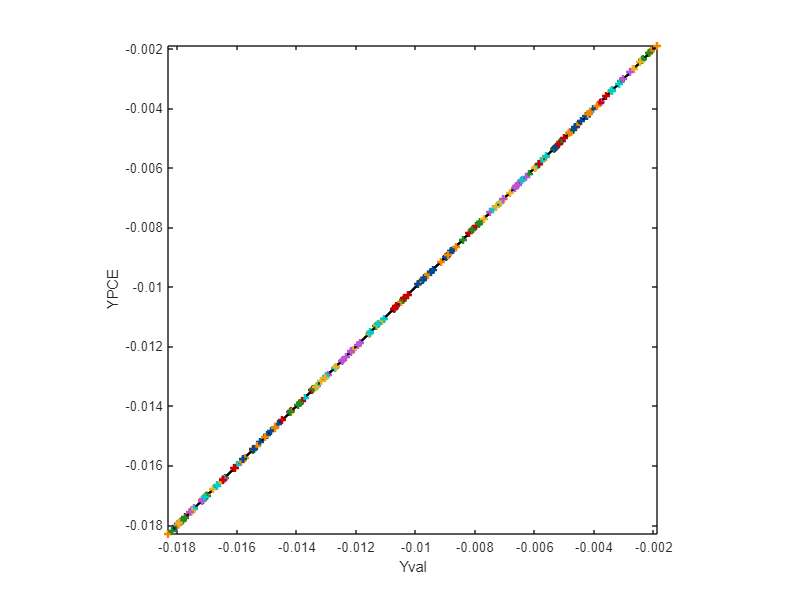

close all;
uq_figure

hold on
uq_plot([min(YPCE,[],'all') max(YPCE,[],'all')], [min(YPCE,[],'all') max(YPCE,[],'all')], 'k')

axis equal
axis([[min(YPCE,[],'all') max(YPCE,[],'all')], [min(YPCE,[],'all') max(YPCE,[],'all')]])
uq_plot(Yval, YPCE, '+')
xlabel('Yval');
ylabel('YPCE');
box on;
hold off;

show the covariance matrix of y_FE-output

FE_output = Yval';
Output_FE_COV = cov(FE_output');
heatmap_FE = heatmap(Output_FE_COV)

heatmap_FE =   HeatmapChart - 属性:

        XData: {50×1 cell}
        YData: {50×1 cell}
    ColorData: [50×50 double]

  显示 所有属性


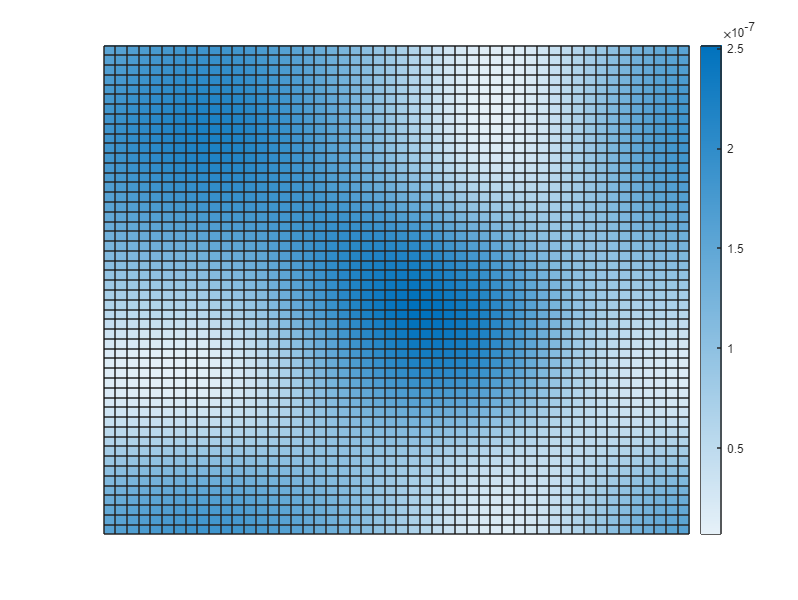

Ax = gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));

show the covariance matrix of PCE-output

N_PCE = size(FE_output,1)

N_PCE = 50

max_len = 15;
PCE_Coeffi_Sum = [];
for i = 1:N_PCE
    PCE_i_Coeffi = myPCE.PCE(i).Coefficients;
    PCE_Coeffi = [PCE_i_Coeffi;zeros(max_len - length(PCE_i_Coeffi),1)];
    PCE_Coeffi_Sum = [PCE_Coeffi_Sum PCE_Coeffi];
end

Calculate the variance of PCE analytically

PCE_Cov = [];
for i = 1:N_PCE
    for j = 1:N_PCE       
        PCE_Cov(i,j) = dot(PCE_Coeffi_Sum(2:15,i),PCE_Coeffi_Sum(2:15,j));
    end
end


show the covariance matrix of PCE

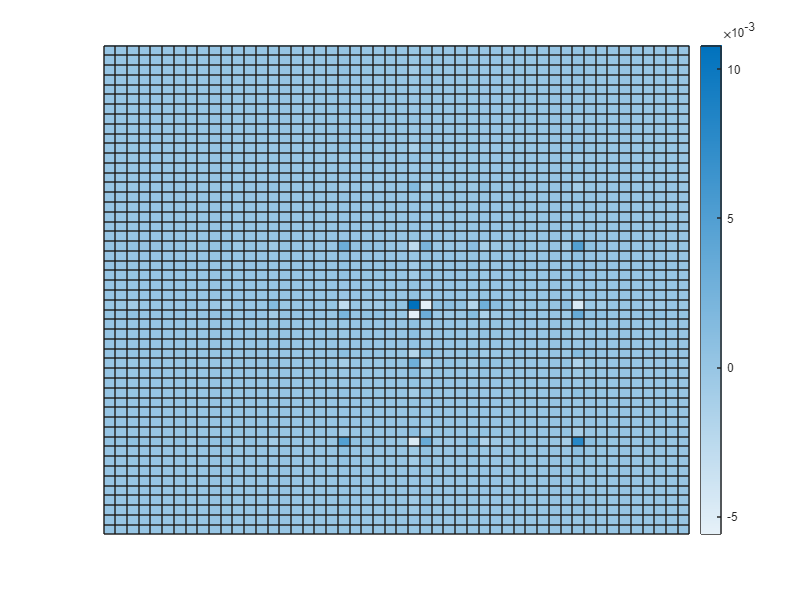

heatmap(PCE_Cov)
Ax = gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));

## 8 - Define the priors for G01/G02 and discrepancy $\sigma$ for Bayesian inference

## **Note: priors for **G01/G02** are different from input models above**

By default, UQlab assumes an independent and identically distributed discrepancy

$G_{01} \sim \mathcal{N}(500,150)$;$G_{02} \sim \mathcal{N}(300,100)$

$\varepsilon \sim \mathcal{N}(0,\mu_{y}^2)$, with $\mu_{y} = \frac{1}{N}\sum_{i = 1}^{N}y_i$

 priors

%Priors on G01 , G02 and sigma

%prior on G01
PriorOpts.Marginals(1).Name = 'G01';               
PriorOpts.Marginals(1).Type = 'Gaussian';
PriorOpts.Marginals(1).Moments   = [500 150];   
PriorOpts.Marginals(1).Bounds = [100 900];

%prior on G02
PriorOpts.Marginals(2).Name = 'G02';              
PriorOpts.Marginals(2).Type = 'Gaussian';
PriorOpts.Marginals(2).Moments   = [300 100];   
PriorOpts.Marginals(2).Bounds = [100 500];

%prior on Sigma2
PriorOpts.Marginals(3).Name = 'sigma2';              
PriorOpts.Marginals(3).Type = 'Uniform';
sigma2 = mean(Raw_Measurement(:,2),"all")

sigma2 = -0.0052

PriorOpts.Marginals(3).Parameters = [0 sigma2.^2];



myPriorDist = uq_createInput(PriorOpts);

% 
% %discrepancy
% SigmaOpts.Name = 'Discrepancy';
% 
% SigmaOpts.Marginals.Name = 'Sigma2';
% SigmaOpts.Marginals.Type = 'Uniform';
% sigma2 = mean(Raw_Measurement(:,2),"all")
% SigmaOpts.Marginals.Parameters = [0 sigma2.^2];
% 
% mySigmaDist = uq_createInput(SigmaOpts);
% 
% 
% DiscrepancyOptsUnknownDisc.Type = 'Gaussian';
% DiscrepancyOptsUnknownDisc.Prior = mySigmaDist;


## 9 - Define the custom-loglikelihood  and measurement data for UQlab calculation


$$\ell\mathcal{L} ({\vec{\theta}},{\epsilon} \mid {Y}) = \prod_{i=1}^{N}\frac{1}{(2\pi)^{{3}/2}\det({\Sigma}(\epsilon))^{1/2}}\exp\left(-\frac{1}{2}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)^{{T}} {\Sigma}(\epsilon)^{-1}\left({Y_i} - \mathcal{M}(\vec{\theta})\right)\right)$$


myData.y = Y_Equal_length_Measurement';
size(myData.y)

ans =      1    50


myData.Name = 'Settlement along the tunnel';

Loglikelihood still follows the Gaussian discrepancy criteria

myLogLikeli = @(params,y) myLogLikeli2(params,y);

## 10 - Solver options


Solver.Type = 'MCMC';
Solver.MCMC.Visualize.Parameters = [1 2 3];
Solver.MCMC.Visualize.Interval = 10;
Solver.MCMC.Sampler = 'AIES';
Solver.MCMC.Steps = 1000;
Solver.MCMC.NChains = 5;
%myProposal.PriorScale = 0.001;

## 11 - Bayesian inference

%BayesOpts.Discrepancy = DiscrepancyOptsUnknownDisc;
%BayesOpts.ForwardModel.Model = myPCE;
BayesOpts.Data = myData;
BayesOpts.Type = 'inversion';
BayesOpts.LogLikelihood = myLogLikeli;
BayesOpts.Solver = Solver;
BayesOpts.Prior = myPriorDist;
BayesAnalysis = uq_createAnalysis(BayesOpts);

The discrepancy was not specified,
using unknown i.i.d. Gaussian discrepancy...

Starting AIES...
Something went wrong while performing the analysis
You may find additional information in the following exception message:


错误使用 uq_GeneralIsopTransform
The input dimension is inconsistent with the data.

出错 uq_PCE_eval (第 55 行)
U = uq_GeneralIsopTransform(X, Input.Marginals, Input.Copula, ED_Input.Marginals, ED_Input.Copula);

出错 uq_eval_uq_metamodel (

## 12 - Post-processing

Burn in 70%; 


uq_postProcessInversionMCMC(BayesAnalysis,'pointEstimate','MAP','percentiles',[0.05,0.95],'burnin',0.7);

uq_print(BayesAnalysis);
%uq_postProcessInversion(BayesAnalysis,'priorPredictive',1000);
uq_display(BayesAnalysis);

## 13 -  Sampling for G01 and G02 (90%CI)

set 90%CI  = 95%- 5%

close all;
uq_postProcessInversionMCMC(BayesAnalysis,'percentiles',[0.05,0.95]);

Obtained the lower bound and upper bound for G01 and G02

G01_5_LowB = BayesAnalysis.Results.PostProc.Percentiles.Values(1,1);
display(G01_5_LowB)

G01_95_UpperB = BayesAnalysis.Results.PostProc.Percentiles.Values(2,1);
display(G01_95_UpperB)
G02_5_LowB = BayesAnalysis.Results.PostProc.Percentiles.Values(1,2);
display(G02_5_LowB)

G02_95_UpperB = BayesAnalysis.Results.PostProc.Percentiles.Values(2,2);
display(G02_95_UpperB)
N_predict = 100

% sampling on G01
G01_90_sample_O = linspace(G01_5_LowB,G01_95_UpperB,N_predict)';
size(G01_90_sample_O)

%Shuffle the order 
shuffledIndices = randperm(length(G01_90_sample_O));
G01_90_sample = G01_90_sample_O(shuffledIndices);
size(G01_90_sample)
% sampling on G02
G02_90_sample_O = linspace(G02_5_LowB,G02_95_UpperB,N_predict)';
size(G02_90_sample_O)
%Shuffle the order 
shuffledIndices = randperm(length(G02_90_sample_O));
G02_90_sample = G02_90_sample_O(shuffledIndices);
size(G02_90_sample)
%plot the sampling on G01 and G02 
figure
plot(G01_90_sample,G02_90_sample,'*');
xlabel('G01');
ylabel('G02');

axis([min(G01_90_sample,[],'all') max(G01_90_sample,[],'all') min(G02_90_sample,[],'all') max(G02_90_sample,[],'all')])

## 14 - 90%  error band

close all;

Predictive FE realization

Predict_sample = [G01_90_sample,G02_90_sample];
size(Predict_sample)

%Loop to get the predictive FE deflection

YPCE_Predict = [];

for i = 1:N_predict
    
    Xval_Predict = Predict_sample(i,:);   

    Deflection = uq_evalModel(myPCE,Xval_Predict);
    YPCE_Predict = [YPCE_Predict;Deflection];


end

size(YPCE_Predict)

Spline curve fitting to smooth the line for the 90CI


for i = 1:size(YPCE_Predict,1)
    
    xi = min(X_Equal_length):0.5:max(X_Equal_length);

    YPCE_Predict_Poly(i,:) = interp1(X_Equal_length',YPCE_Predict(i,:),xi);
end
size(YPCE_Predict_Poly)

Loop to fill the error band 90%CI

%loop to fill the error band

for i = 1:size(YPCE_Predict_Poly,1)-1
    hold on;
    fill([xi fliplr(xi)], [YPCE_Predict_Poly(i,:) fliplr(YPCE_Predict_Poly(i+1,:))], 'cyan', 'FaceAlpha', 1,'EdgeColor','none');
end

 hold on;
 
 xlabel('Distance \rm(m)','FontSize',10);
 pbaspect([1 0.3 1]);
 ax = gca;
 ax.XAxisLocation = 'top';
 ylabel('Settlement (m)','FontSize',10);
 box on;
 set(ax,'FontSize',10);
 yticks('auto');
 %ylim([-3.5 0])

scatter the measurement

for i = 1: size(myData.y,1)
    scatter(X_Equal_length,myData.y(i,:),'black','x');
    hold on;
end

draw the mean value of 90%CI

plot(xi,mean(YPCE_Predict_Poly),'red','LineWidth',1.5);